# **Esercitazione 2 - EEG**

**Obiettivo 1: Realizzare una funzione che permetta di caricare automaticamente i dati.**

***reminder: AD è patologico (Alzheimer's disease), C è fisiologico (healthy control)***

my_importdata;

**Obiettivo 2: Calcolare e visualizzare lo spettro di densità di potenza per ogni dato EEG.**

%DEFINISCO UN OVERLAP
overlap=90;

%DEFINISCO LA LUNGHEZZA DELLA FINESTRA TEMPORALE
window=100;

%FREQUENZA DI CAMPIONAMENTO
fs=100;

%nfft è il numero 1024
%The default nfft is the greater of 256 or the next power of 2 greater than the length of the segments.


%CONSIDERO I MALATI
%prendo fuori i valori del primo paziente per poi concatenare gli array di
%potenze medie
%PER ACCEDERE ALLE MATRICI RELATIVE AI PAZIENTI CHE SONO CONTENUTE NEL CELL
%ARRAY USO LA FUNZIONE cell2mat

[potenza_AD, freq_AD ]=my_pwelch(cell2mat(AD(1) ) ,overlap, window, 1024, fs);
%ciclo for che parte da 2,
for index=2:length(AD)
    [PXX, freq ]=my_pwelch(cell2mat(AD(index) ) ,overlap, window, 1024, fs);
    potenza_AD = [potenza_AD, PXX];
end

%RIPETO PER I SANI
[potenza_C, freq_C ]=my_pwelch(cell2mat(C(1) ) ,overlap, window, 1024, fs);

for index=2:length(C)
    [PXX, freq ]=my_pwelch(cell2mat(C(index) ) ,overlap, window, 1024, fs);
    potenza_C = [potenza_C, PXX];
end

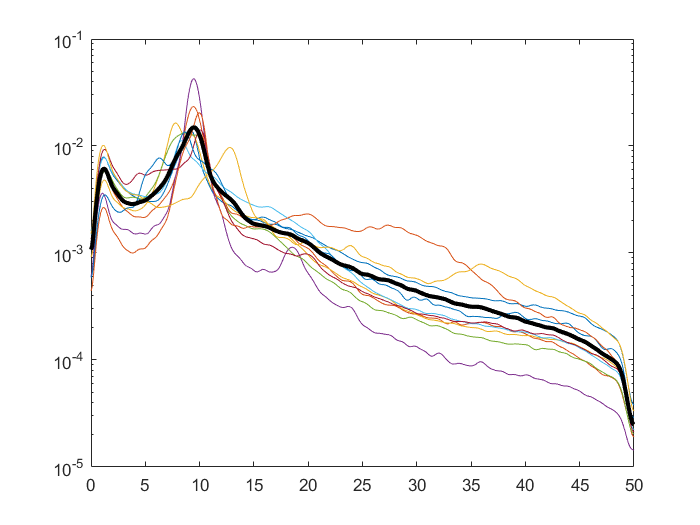

%PROVA DI PLOT
%     
% figure
% plot(freq_AD, potenza_AD)
% figure
% semilogx(freq_AD, potenza_AD)
figure
semilogy(freq_AD, potenza_AD)
hold on
semilogy(freq_AD, mean (potenza_AD,2), 'Color', 'k', "LineWidth", 2.5)

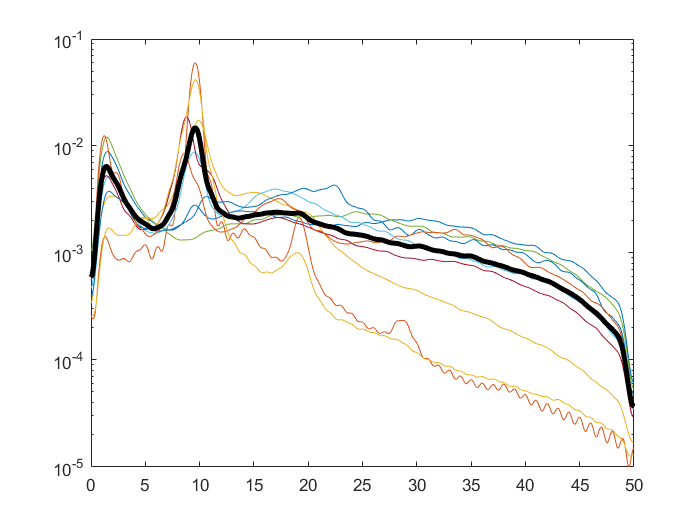

figure
semilogy(freq_C,potenza_C)
hold on
semilogy(freq_C,mean (potenza_C,2) , 'Color' , 'k' , "LineWidth", 3)

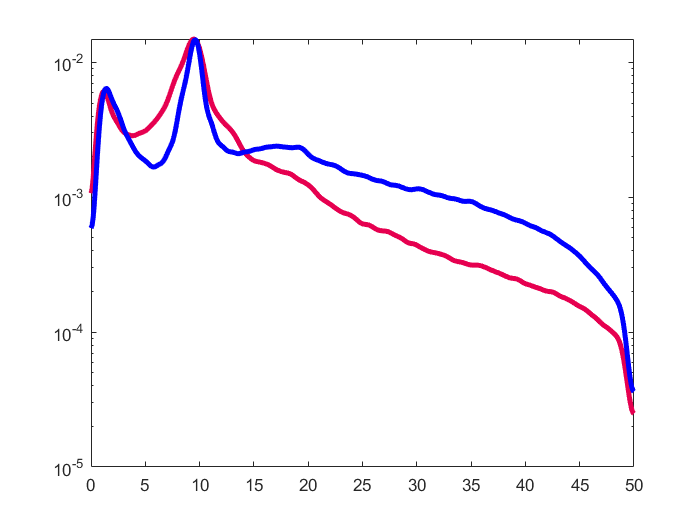

%PLOT DEGLI SPETTRI DI POTENZA MEDI
medio_AD = mean (potenza_AD,2);
medio_C = mean (potenza_C,2);

figure
semilogy(freq_AD, medio_AD , "Color", "#E60050" , "LineWidth", 3)
hold on
semilogy(freq_C, medio_C , "Color", "b" , "LineWidth", 3)

Visualizzazione dello spettro di potenza medio includendo anche l’intervallo di confidenza..

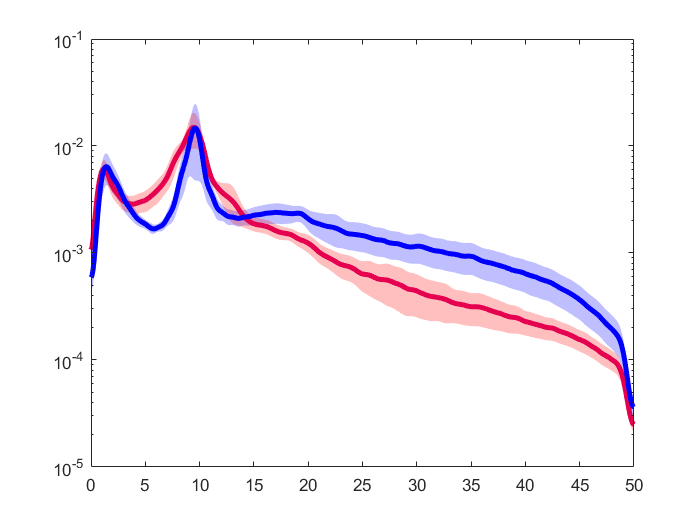

hold on
my_fillbetween(potenza_AD, medio_AD, freq_AD, 'r');
my_fillbetween(potenza_C, medio_C, freq_C, 'b');

**Obiettivo 3: Calcolare i valori di Potenza Assoluta e Relativa per ogni gruppo.**

%calcolo potenza assoluta e potenza relativa per il gruppo AD
[abs_pow_A1, rel_pow_A1] = compute_abs_rel_power(medio_AD, 2, 4, freq_AD);
[abs_pow_B1, rel_pow_B1] = compute_abs_rel_power(medio_AD, 5, 7, freq_AD);
[abs_pow_C1, rel_pow_C1] = compute_abs_rel_power(medio_AD, 8, 13, freq_AD);
[abs_pow_D1, rel_pow_D1] = compute_abs_rel_power(medio_AD, 14, 30, freq_AD);

%calcolo potenza assoluta e potenza relativa per il gruppo C
[abs_pow_A2, rel_pow_A2] = compute_abs_rel_power(medio_C, 2, 4, freq_C);
[abs_pow_B2, rel_pow_B2] = compute_abs_rel_power(medio_C, 5, 7, freq_C);
[abs_pow_C2, rel_pow_C2] = compute_abs_rel_power(medio_C, 8, 13, freq_C);
[abs_pow_D2, rel_pow_D2] = compute_abs_rel_power(medio_C, 14, 30, freq_C);

**Obiettivo 4: Visualizzare i valori di Potenza Assoluta e Relativa**

 Visualizzazione di media e varianza dei valori di potenza relativa e assoluta.

**Obiettivo 5: Applicazione test t-Student.**